# **Plot Cdt1 mutant degradation kinetics**

Cell line: MCF10A, YFP-PCNA, pCW_Cdt1-mCherry(45), pCW_Cdt1delPIP-mCherry(79), pCW_Cdt1delCy-mCherry(80)

Microscope: 20x 3x3 stitched image

Imaging: 3 min interval

**Testing for:**

- Cdt1 degradation relative to PCNA loading

**Annotations**

- PCNA start (multiple thresholds)

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
load([dataDir filesep 'C230_data.mat'],'S','settings','allIF');
% S = loadData(conditions, dataDir);
conditions = settings.conditions

conditions = 3×6 cell array
    {'Cdt1'       }    {1×2 double}    {1×3 double}    {1×9 double}    {1×3 double}    {1×2 double}
    {'Cdt1-delPIP'}    {1×2 double}    {1×3 double}    {1×9 double}    {1×3 double}    {1×2 double}
    {'Cdt1-delCy' }    {1×2 double}    {1×3 double}    {1×9 double}    {1×3 double}    {1×2 double}




framesPerHr = 60/3;
frameDrugAdded = 20;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
    S(i).POI_realtime = S(i).POI/framesPerHr;
end

## **Plot traces  aligned to S phase start (PCNA foci)**

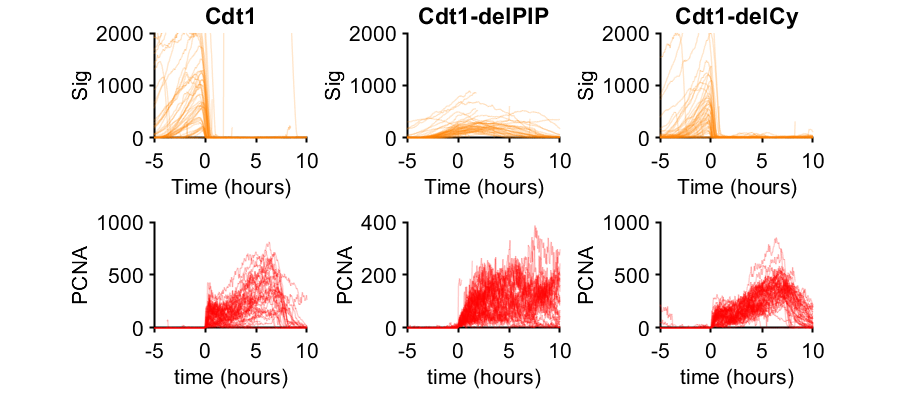

conds=[1 2 3];
xlims = {[-5 10]};
figure('pos',[10 10 length(conds)*300 400 ]),
for i=1:length(conds)
    
    inds = S(conds(i)).sigExpress & S(conds(i)).POI(:,1) < 60 & (S(conds(i)).filterPOI(:,4) - S(conds(i)).POI(:,1) > 60);
    
    cells = find(inds);
    for numcell = randsample(cells,min([50 length(cells)]))'
        %             timeAligned = (xFrames-S(conds(i)).POI(numcell,poiAlign(p)))/framesPerHr;
        POI_point = S(conds(i)).filterPOI(numcell,4) ;
        timeAligned =(xFrames-POI_point)/framesPerHr;
        
        subplot(2,length(conds),i),hold on
        patchline(timeAligned,(S(conds(i)).sigNuc(numcell,:)),...
            'edgecolor',[1 0.5 0],'linewidth',1,'edgealpha',0.2);
        title(conditions(conds(i),1));
        ylabel('Sig');
                    ylim([0 2000]);
        xlim(xlims{1});
        xlabel('Time (hours)');
        subplot(2,length(conds),i+length(conds)),hold on
        patchline(timeAligned,S(conds(i)).filterArea(numcell,:,4),...
            'edgecolor','r','linewidth',1,'edgealpha',0.2);
        ylabel('PCNA');
        xlabel('time (hours)');
        % ylim([0 1]);
        xlim(xlims{1});
    end
end

**Gate cells**

filter_gate = 4;
for c = 1:length(S)
    gate = false(length(S(c).area(:,1)),1);    
        S(c).sigNucNorm = S(c).sigNuc./max(S(c).sigNuc,[],2);
    for i = 1:length(S(c).area(:,1))
        prePOIstart = S(c).filterPOI(i,filter_gate) - 2*framesPerHr;
        prePOIend = S(c).filterPOI(i,filter_gate) - 0.1*framesPerHr;
        if prePOIstart > 0
               pcna_pre = S(c).filterArea(i,prePOIstart:prePOIend,filter_gate);
               puncta_frames = sum(pcna_pre > 2);
                if puncta_frames < 2
                    gate(i) = true;
                end
        end
        if  max(diff(S(c).sigNuc(i,:))) > 100 | max(S(c).sigNuc(i,:)) > 600 | max(S(c).sigNuc(i,:)) < 200
           gate(i) = false;
        end
        if S(c).filterPOI(i,filter_gate) - 0.5*framesPerHr > 0
            if S(c).sigNuc(i,S(c).filterPOI(i,filter_gate) - 0.5*framesPerHr) < 50 | ...
                    S(c).sigNuc(i,S(c).filterPOI(i,filter_gate) - 0.5*framesPerHr) > 1000
                gate(i) = false;
            end
        end
        if min(S(c).sigNucNorm(i,:)) < -.05
            gate(i) = false;
        end
    end
    S(c).gate = gate;
    disp(sprintf('%d cells left over after gate cond %d',sum(S(c).gate),c))

end

700 cells left over after gate cond 1
707 cells left over after gate cond 2
555 cells left over after gate cond 3


## **Plot traces  aligned to S phase start (PCNA foci) gated for proper S phase start call**

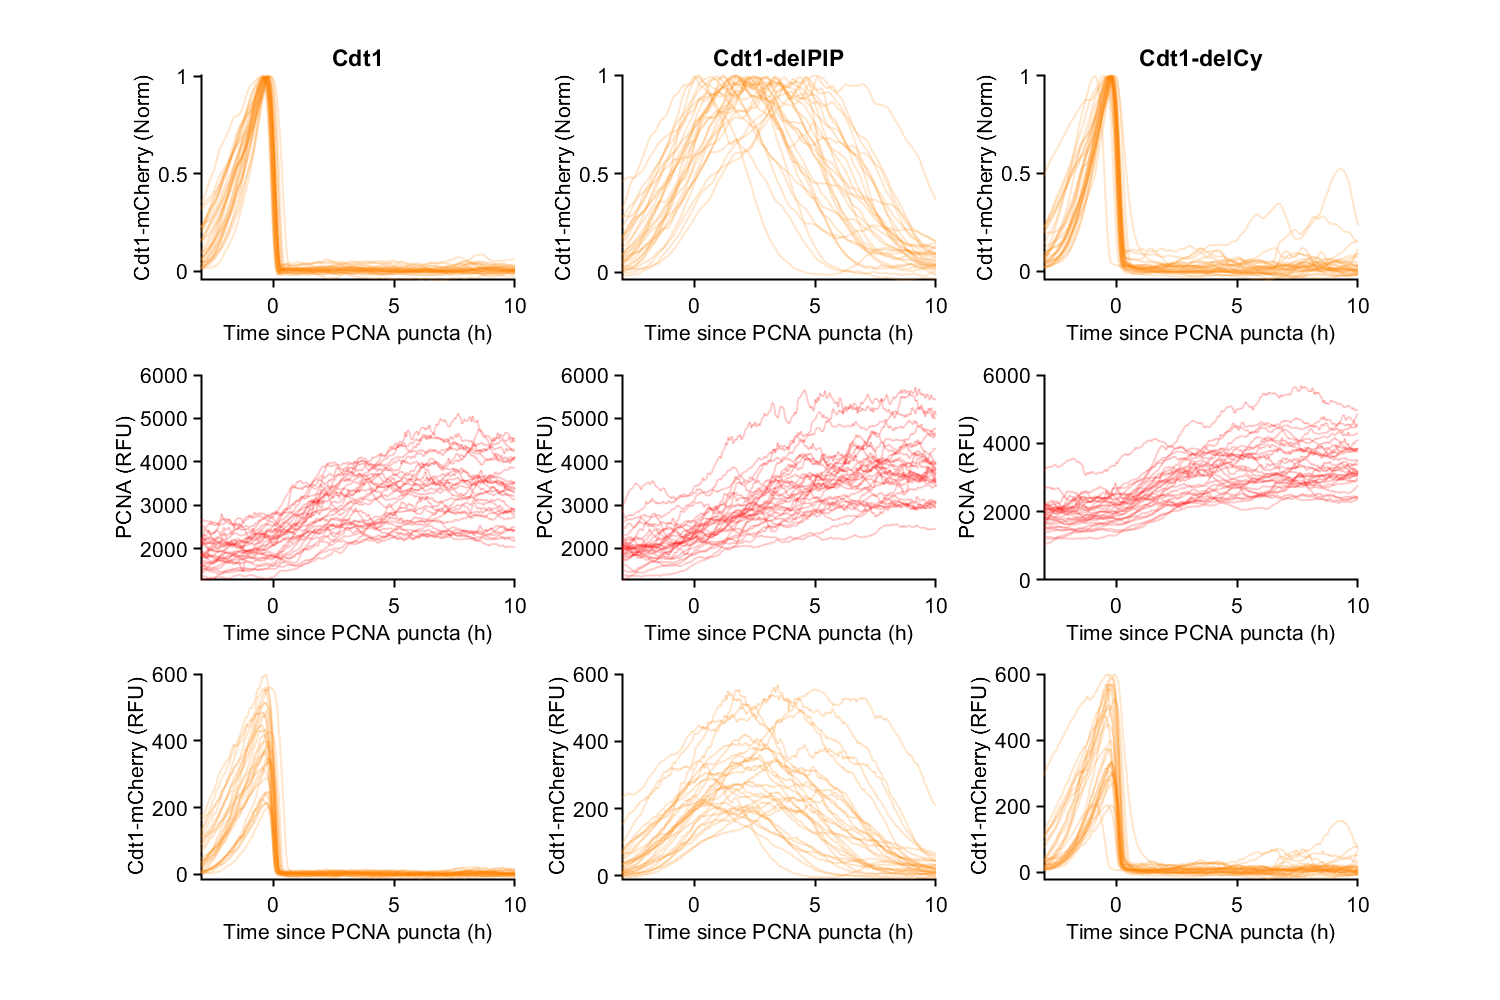

conds=[1 2 3];
xlims = {[-3 10]};
rng(10)
figure('pos',[10 10 length(conds)*500 1000 ]),
for i=1:length(conds)
    
    inds = S(conds(i)).gate & S(conds(i)).sigExpress & S(conds(i)).POI(:,1) < 6*framesPerHr &...
        (S(conds(i)).filterPOI(:,4) - S(conds(i)).POI(:,1) > 4*framesPerHr) & ...
        S(conds(i)).traceStats(:,2) - S(conds(i)).filterPOI(:,4) > 10*framesPerHr ;
    
    cells = find(inds);
    for numcell = randsample(cells,min([30 length(cells)]))'
        %             timeAligned = (xFrames-S(conds(i)).POI(numcell,poiAlign(p)))/framesPerHr;
        POI_point = S(conds(i)).filterPOI(numcell,4) ;
        timeAligned =(xFrames-POI_point)/framesPerHr;
        
        subplot(3,length(conds),i),hold on
        patchline(timeAligned,nansmoothm(S(conds(i)).sigNucNorm(numcell,:),9,'sgolay'),...
            'edgecolor',[1 0.5 0],'linewidth',1.5,'edgealpha',0.2);
        title(conditions(conds(i),1));
        ylabel('Cdt1-mCherry (Norm)');
        %             ylim([0 2]);
        xlim(xlims{1});
        xlabel('Time since PCNA puncta (h)');
        subplot(3,length(conds),i+length(conds)),hold on
%         patchline(timeAligned,S(conds(i)).filterArea(numcell,:,4),...
%             'edgecolor','r','linewidth',1.5,'edgealpha',0.2);
patchline(timeAligned,S(conds(i)).pcnaNuc(numcell,:),...
            'edgecolor','r','linewidth',1.5,'edgealpha',0.2);
        ylabel('PCNA (RFU)');
        xlabel('Time since PCNA puncta (h)');
        % ylim([0 1]);
        xlim(xlims{1});
        
        subplot(3,length(conds),i+2*length(conds)),hold on
        patchline(timeAligned,(S(conds(i)).sigNuc(numcell,:)),...
            'edgecolor',[1 0.5 0],'linewidth',1.5,'edgealpha',0.2);
        ylabel('Cdt1-mCherry (RFU)');
        xlabel('Time since PCNA puncta (h)');
        % ylim([0 1]);
        xlim(xlims{1});
    end
end

**Mean cdk traces post CRL4**

conds = [1 3 2];
timeGate = [ 0 6];
POI_align = 4;
figure('unit','inches','position',[0 0 4 4])
hold on
cols = lines(3);
for i=1:length(conds)
    c = conds(i);
    data = S(c);
 inds = data.gate & data.sigExpress & data.POI(:,1) < 6*framesPerHr &...
    (data.filterPOI(:,4) - data.POI(:,1) > 4*framesPerHr) & ...
    data.traceStats(:,2) -data.filterPOI(:,POI_align) > 10*framesPerHr;
    ydata = smoothdata(data.sigNucNorm(inds,:),5,'sgolay');

    POI = data.filterPOI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
%     errorbar((frames)/framesPerHr,medSig,2*semCRL,'LineWidth',1.5);
        shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',cols(i,:),'LineWidth',1});

%         [frames, medSig, semCRL] =get_median_trace(ydata,POI,1);
%         plot((frames)/framesPerHr,medSig,'LineWidth',1.5);
sum(inds)
end

ans = 306

ans = 255

ans = 192

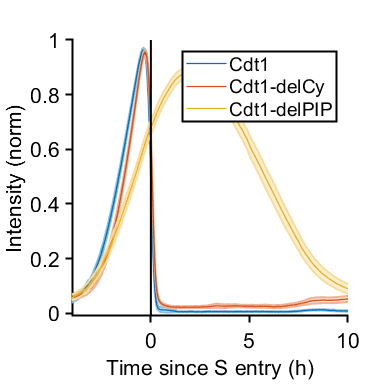


ylabel('Intensity (norm)');xlabel('Time since S entry (h)');
legend(conditions(conds,1))
xlim([-4 10]); 
ylim([-.01 1]);
axis square
vline([0],'k')
print_pdf([pwd() '\Figs\mean_traces.pdf'])

## **Plot traces aligned**

cells = 306

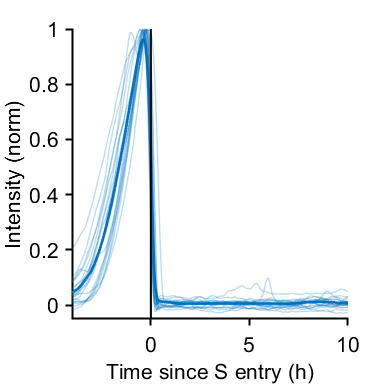

cells = 192

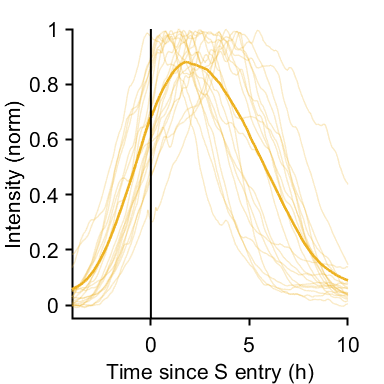

cells = 255

rng(1)
conds=[1 2 3];
poiAlign = 4;

cols = lines(3);
cols = cols([1 3 2],:);

for i=1:length(conds)
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
    hold on
    data = S(conds(i));
    inds = data.gate & data.sigExpress & data.POI(:,1) < 6*framesPerHr &...
        (data.filterPOI(:,4) - data.POI(:,1) > 4*framesPerHr) & ...
        data.traceStats(:,2) -data.filterPOI(:,poiAlign) > 10*framesPerHr;
    indplot = (data.traceStats(:,2)-data.filterPOI(:,poiAlign))/framesPerHr > 10;
    cells = find(inds);
    cellsplot = find(inds & indplot);
    for numcell = randsample(cellsplot,min([20 length(cellsplot)]))'
        timeAligned = (xFrames-data.filterPOI(numcell,poiAlign))/framesPerHr;
        patchline(timeAligned(1:end),nansmoothm(data.sigNucNorm(numcell,:),9,'sgolay'),'edgecolor',cols(i,:),'LineWidth',1,'edgealpha',.25);
        %([conditions{conds(i),1} ' aligned to ' alignNames{(p)}]);
        ylabel('Intensity (norm)');
        ylim([-.05 1]);
        xlim([-4 10]);
        %             xticks([-8:2:4])
        xlabel('Time since S entry (h)');
    end
    
    ydata = smoothdata(data.sigNuc(cells,:)./max(data.sigNuc(cells,:),[],2),5,'sgolay');

    [frames, medSig, semCRL] =get_mean_trace(ydata,data.filterPOI(cells,poiAlign),0);
    plot((frames)/framesPerHr,medSig,'k','LineWidth',2,'Color',cols(i,:))
    cells = length(cells)
    vline(0,'k')
    print_pdf([pwd() '\Figs\example_traces_' num2str(conds(i))])
end

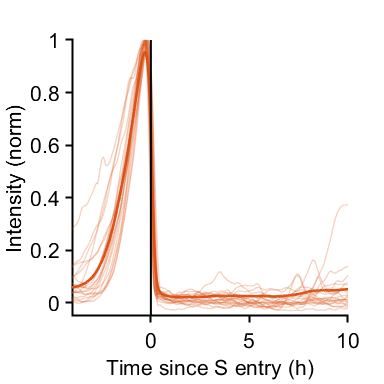

hold off
axis square